addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

Question 3, part a)

xs = [0 1 2 3 4 5];
ys = [0 0.45 1.06 1.37 2.25 2.47];
poly = interpLagrange(xs, ys)

$$poly = -\frac{343\,x^{5}}{12000}+\frac{273\,x^{4}}{800}-\frac{3383\,x^{3}}{2400}+\frac{1879\,x^{2}}{800}-\frac{4811\,x}{6000}$$

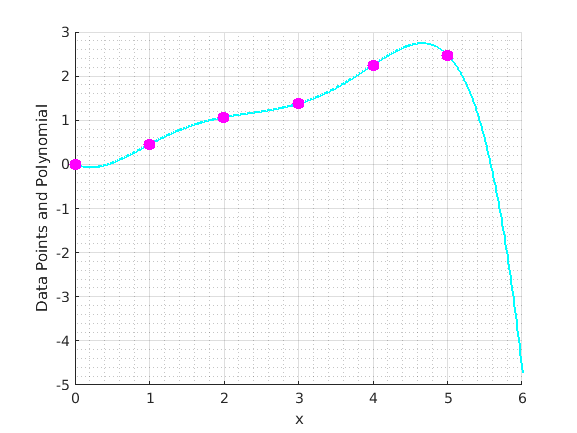

plotPoly(xs, ys, poly, [min(xs), 6])

Question 3, part b)

xs2 = [0 1 2 3 4 5];
ys2 = [0 0.45 1.06 1.73 2.25 2.47];
poly2 = interpLagrange(xs2, ys2)

$$poly2 = \frac{17\,x^{5}}{12000}-\frac{3\,x^{4}}{160}+\frac{29\,x^{3}}{480}+\frac{7\,x^{2}}{800}+\frac{2389\,x}{6000}$$

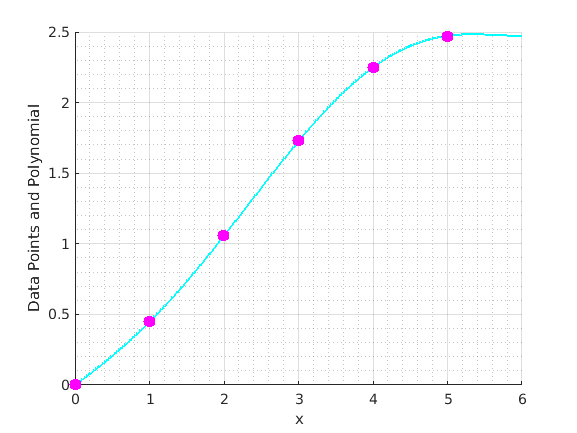

plotPoly(xs2, ys2, poly2, [min(xs2), 6])

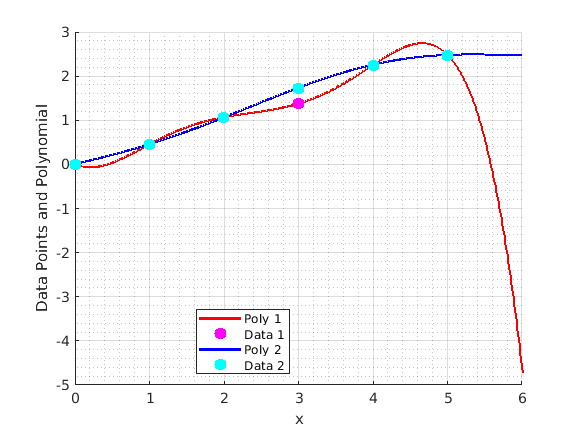

% comparing the plots
plotComparePoly(xs, ys, xs2, ys2, 0, 6, poly, poly2)

%difference between the two estimates at x = 3
calcPoly(poly, 3) - calcPoly(poly2, 3)

$$ans = -\frac{9}{25}$$

% difference between the two estimates at x = 6 (extrapolation)
calcPoly(poly2, 6) - calcPoly(poly, 6)

$$ans = \frac{36}{5}$$

vpa(calcPoly(poly2, 6) - calcPoly(poly, 6))

$$ans = 7.2$$